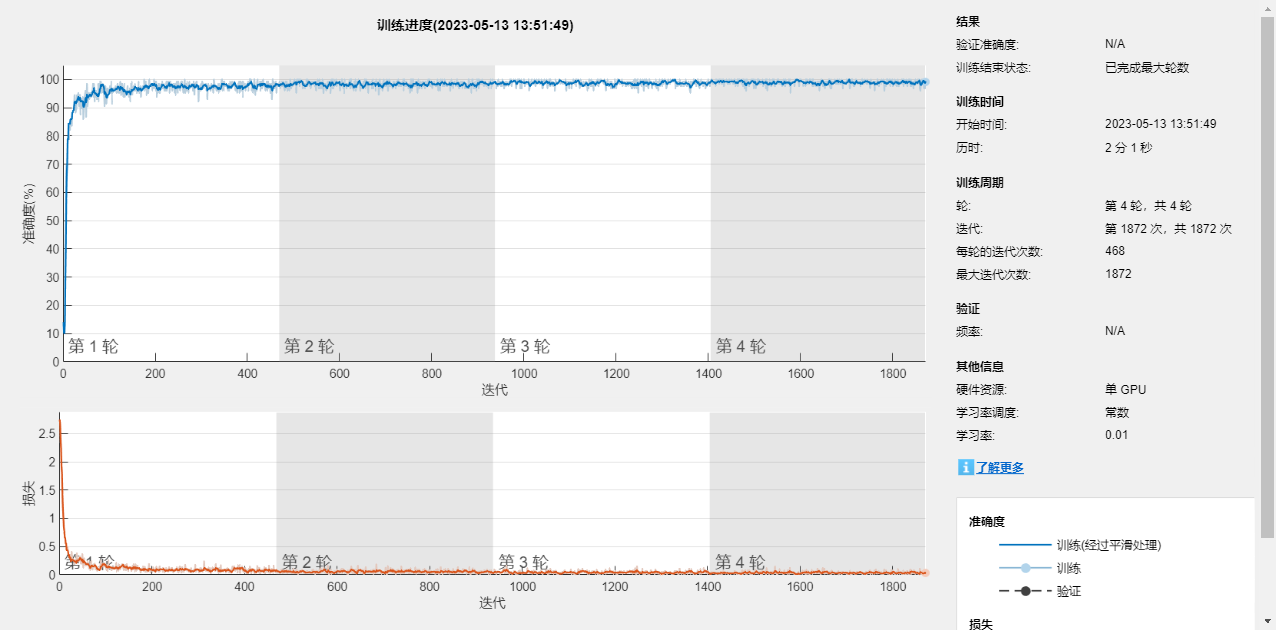

%% 读取数据
images_train=LoadMNISTImages('train-images.idx3-ubyte');
images_test=LoadMNISTImages('t10k-images.idx3-ubyte');
labels_train=LoadMNISTLabels('train-labels.idx1-ubyte');
labels_test=LoadMNISTLabels('t10k-labels.idx1-ubyte');
%% 数据格式转换
X_Train = zeros(28,28,1,60000);
%MATLAB深度学习需要构建四维矩阵，含义为长X宽X颜色通道X训练集图像数
for i = 1:60000
temp = images_train(:,i);
X_Train(:,:,1,i) = reshape(temp,28,28);
end
Y_Train = categorical(labels_train);%训练集标签的类型转换
X_Test = zeros(28,28,1,10000);%测试集数据转换
for i = 1:10000
temp = images_test(:,i);
X_Test(:,:,1,i) = reshape(temp,28,28);
end
Y_Test = categorical(labels_test);%测试集标签转换
%% 深度学习的网络结构
layers = [ ...
imageInputLayer([28,28,1]) %输入层
convolution2dLayer(3,8,'Padding','same') %3X3的8个通道卷积层， 0延拓
batchNormalizationLayer %分组归一化层
reluLayer %ReLu操作
maxPooling2dLayer(2,'Stride',2) %最大值池化层
convolution2dLayer(3,16,'Padding','same') %3X3的16个通道卷积层， 0延拓
batchNormalizationLayer
reluLayer
maxPooling2dLayer(2,'Stride',2)
convolution2dLayer(3,32,'Padding','same') %3X3的32个通道卷积层， 0延拓
batchNormalizationLayer
reluLayer
fullyConnectedLayer(10) %全连接层，对应10种分类输出
softmaxLayer %Softmax层增大输出区分度
classificationLayer %分类器层
];
%% 深度学习参数设置
options = trainingOptions('sgdm', ...
'InitialLearnRate',0.01, ...
'MaxEpochs',4, ...
'Shuffle','every-epoch', ...
'Verbose',false, ...
'Plots','training-progress');
%% 训练（一行代码）
net=trainNetwork(X_Train,Y_Train,layers, options); %训练

%% 测试
Y_pred = classify(net, X_Test); %测试
accy = sum(Y_pred == Y_Test) / length(Y_Test) %计算准确度

accy = 0.9875